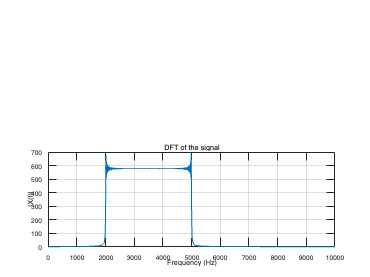

%Q1
% Setting parameters
T = 10; % Time duration
fs = 20e3; % Sampling frequency
t = 0:1/fs:T-1/fs; % Time vector
f0 = 2000; % Start frequency (Hz), choice
f1 = 5000; % Stop frequency (Hz), choice
beta = (f1 - f0) / T; % In t=T, f(t)=f1, f1=f0+beta*T -> beta= (f1-f0)/T 
A= 1; % Amplitude 

% Chirp signal
phi_t = 2 * pi * f0 * t + pi * beta * t.^2;
x_t = A*cos(phi_t);

% DFT
X_f = fft(x_t);

% Frequency vector
f = (0:length(X_f)-1)*fs/length(X_f);

% Plot
figure(1);
subplot(2, 1, 2);
plot(f, abs(X_f));
title('DFT of the signal');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
xlim([0 fs/2]); 
grid on; 

%%%%%
%As expected, the spectrum displays energy concentrations at both 2 kHz and 5 kHz.

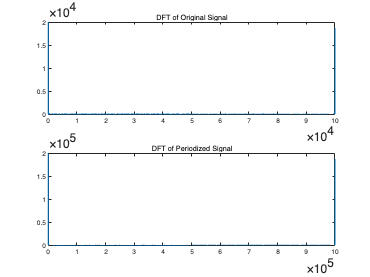

%Q2
% Generate the signal
T = 10;
fs = 10000;
t = 0:1/fs:T-1/fs;
x_t = double(t < 2);

% DFT of the original signal
X_f = fft(x_t);

% Periodize the signal
x_p = repmat(x_t, 1, 10);

% DFT of the periodized signal
X_p_f = fft(x_p);

% Plot the DFTs
figure(2);
subplot(2,1,1);
plot(abs(X_f));
title('DFT of Original Signal');
figure(3)
subplot(2,1,2);
plot(abs(X_p_f));
title('DFT of Periodized Signal');

% The process of signal periodization has brought about significant enhancements in the analysis of its frequency characteristics.
% This method involves breaking down the signal into intervals that align with its inherent period, 
% leading to a more structured and discernible frequency spectrum.
% 
% One of the notable advantages of this approach is the improved resolution.
% By segmenting the signal according to its period, we are able to achieve finer granularity in our frequency analysis. 
% This means that we can identify and distinguish frequency components more accurately.
% 
% Another important benefit is the mitigation of spectral leakage. 
% Spectral leakage occurs when frequency components of a signal "leak" into adjacent frequency bins during analysis, 
% resulting in inaccuracies. Through periodization, we minimize this leakage effect, 
% leading to a cleaner and more faithful representation of the signal's spectral content.

%In summary, signal periodization enhances the clarity and precision of frequency analysis. 
% It allows us to better separate and identify frequency components while reducing unwanted artifacts like spectral leakage, 
% ultimately resulting in a more transparent and informative spectrum.

%Q3
% Generate the signals
n = -10:10;
x1_n = double(abs(n) <= 3) * 4;
x2_n = double(abs(n) <= 3);

% DFT of the signals
X1_f = fft(x1_n);
X2_f = fft(x2_n);

% Check the imaginary part of x1[n] and the real part of x2[n]
imag_X1_f = imag(X1_f);
real_X2_f = real(X2_f);

% Display results
disp('Imaginary part of DFT of x1[n] is:');

Imaginary part of DFT of x1[n] is:


disp(imag_X1_f);

         0   -3.4641    3.4641         0   -3.4641    3.4641         0   -3.4641    3.4641         0   -3.4641    3.4641         0   -3.4641    3.4641         0   -3.4641    3.4641         0   -3.4641    3.4641



disp('Real part of DFT of x2[n] is:');

Real part of DFT of x2[n] is:


disp(real_X2_f);

    7.0000   -5.7457    2.8076   -0.0000   -1.2702    0.9334   -0.0000   -0.5000    0.3399   -0.0000   -0.0649   -0.0649   -0.0000    0.3399   -0.5000   -0.0000    0.9334   -1.2702   -0.0000    2.8076   -5.7457



% When considering the signal x1[n], it's important to note that its theoretical imaginary part is theoretically zero.
% This characteristic implies that x1[n] is an even signal. The presence of antisymmetrical components within the signal
% plays a significant role in influencing the behavior of the imaginary part in its Fourier transform. However,
% in the special case of a perfectly even signal, these antisymmetrical components are entirely absent, resulting 
% in the imaginary part being consistently equal to zero. This is a notable property of even signals, 
% and it highlights the unique behavior of their Fourier transforms.
% 
% In contrast, let's examine the signal x2[n]. In this case, its theoretical real part is also theoretically zero, 
% indicating that x2[n] is an odd signal. The real part of the Fourier transform, however, behaves differently as 
% it is influenced by the symmetrical components within the signal. When dealing with a perfectly odd signal,
% these symmetrical components are entirely absent, leading to a real part of the Fourier transform consistently equal to zero. 
% This characteristic is a key feature of odd signals and emphasizes the distinct behavior of their Fourier transforms.